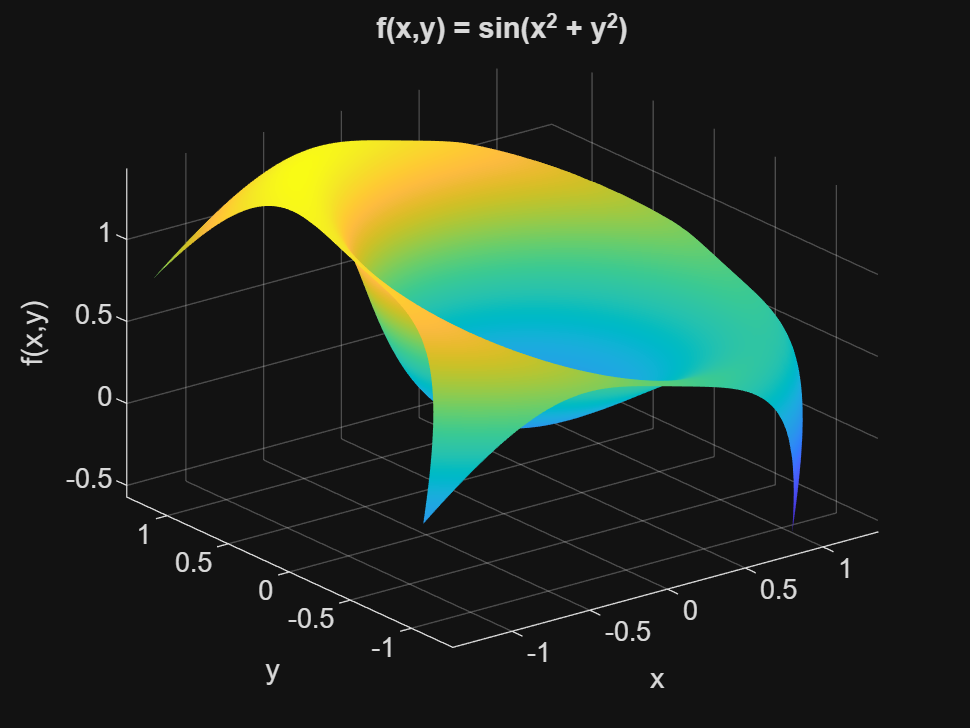

%1
%A
x = (2*rand(1,200)-1).*sqrt(pi/2);
y = (2*rand(1,200)-1).*sqrt(pi/2);

x = sort(x);
y = sort(y);

[X,Y] = meshgrid(x,y);
Z = sin(X.^2 + Y.^2);

figure;
h1 = surf(X,Y,Z);

colormap(parula);
shading interp;

rotate(h1,[1 0 0],15);
rotate(h1,[0 1 0],15);
view(3);

xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('f(x,y) = sin(x^2 + y^2)');

grid on;
axis tight;

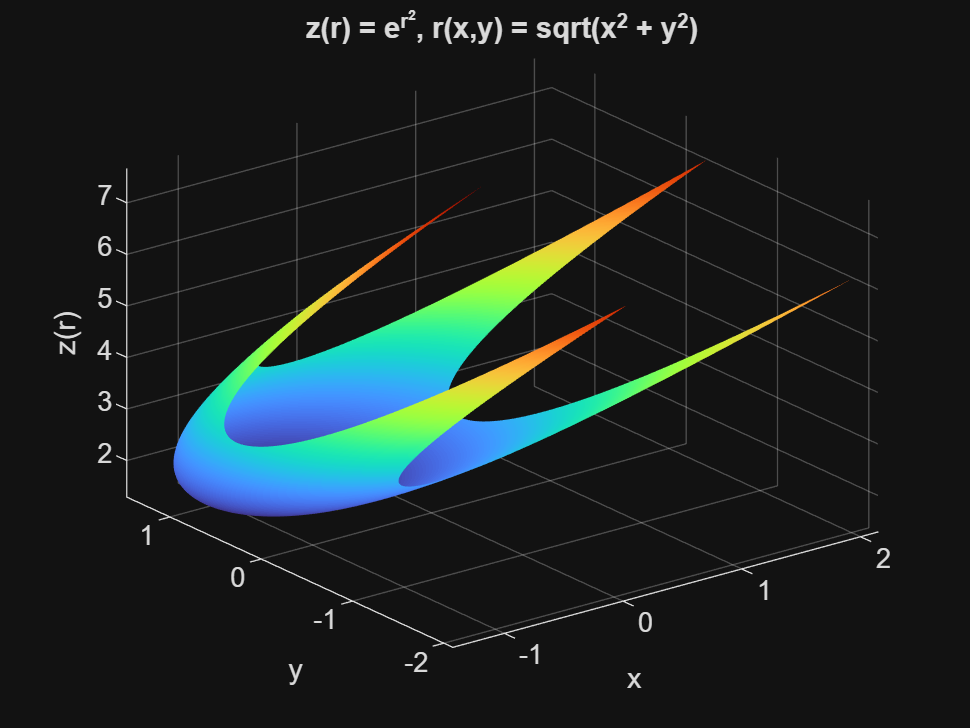

%B
x = linspace(-1,1,200);
y = linspace(-1,1,200);

[X,Y] = meshgrid(x,y);

R = sqrt(X.^2 + Y.^2);

Z = exp(R.^2);

figure;
h2 = surf(X,Y,Z);

colormap(turbo);
shading interp;

rotate(h2,[1 0 0],20);
rotate(h2,[0 1 0],20);

view(3);

xlabel('x');
ylabel('y');
zlabel('z(r)');
title('z(r) = e^{r^2}, r(x,y) = sqrt(x^2 + y^2)');

grid on;
axis tight;

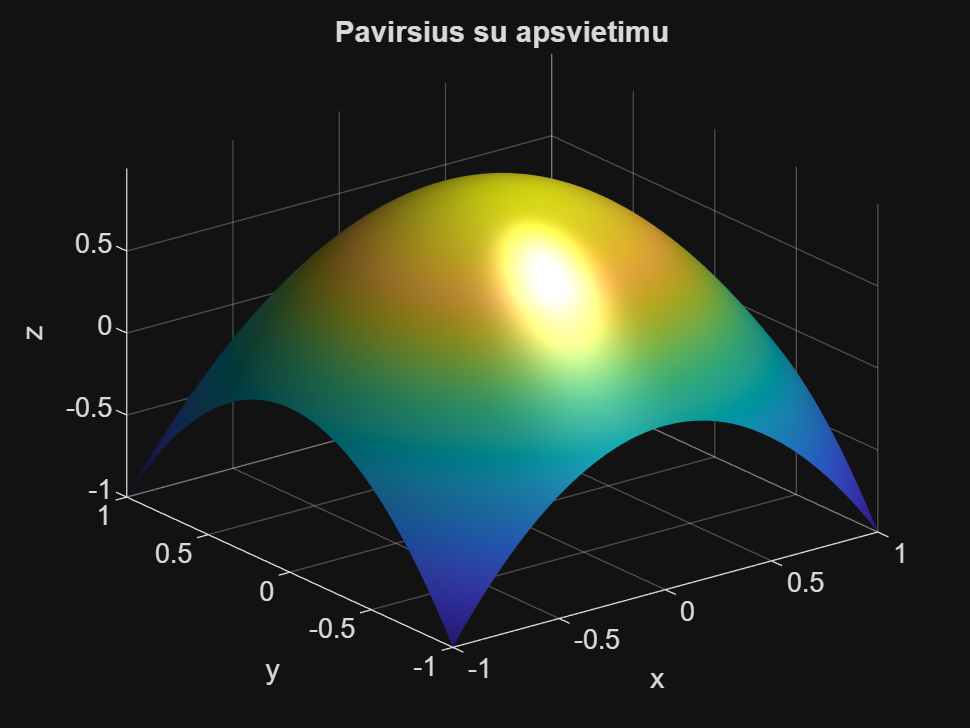

clear
%P. Funkcijos "surf" savybes
x = linspace(-1,1,100);
y = linspace(-1,1,100);

[X,Y] = meshgrid(x,y);

Z = 1 - (X.^2 + Y.^2);


%A
figure;

surf(X,Y,Z);
shading interp;
camlight;
lighting gouraud;

xlabel('x');
ylabel('y');
zlabel('z');
title('Pavirsius su apsvietimu');

grid on;
axis tight;
view(3);
colormap(parula);

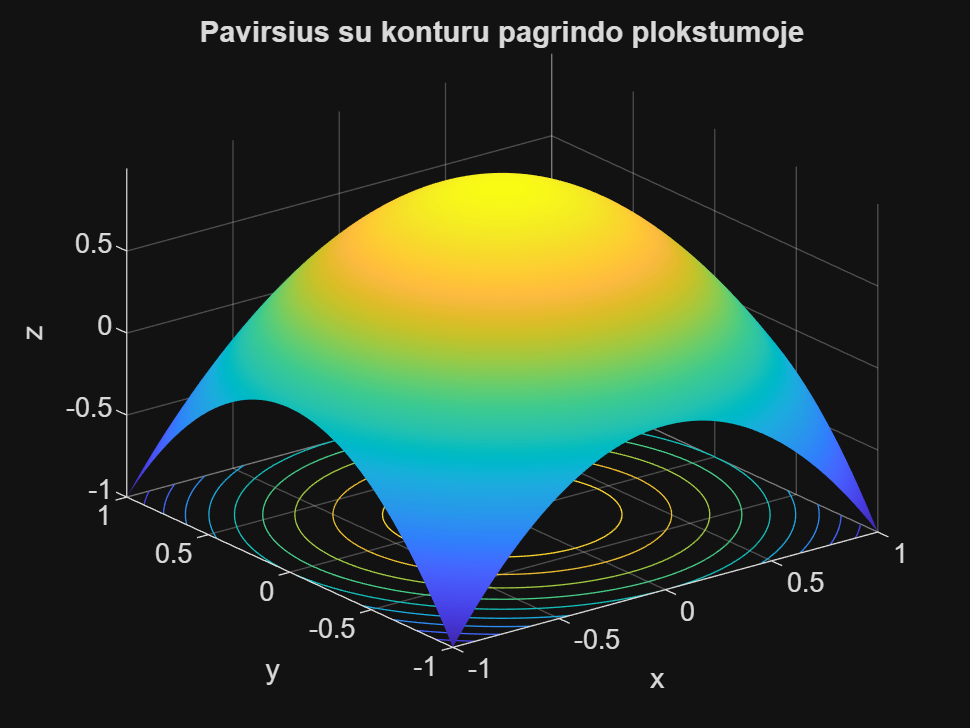



%B
figure;

surfc(X,Y,Z);
shading interp;

xlabel('x');
ylabel('y');
zlabel('z');
title('Pavirsius su konturu pagrindo plokstumoje');

grid on;
axis tight;
view(3);
colormap(parula);

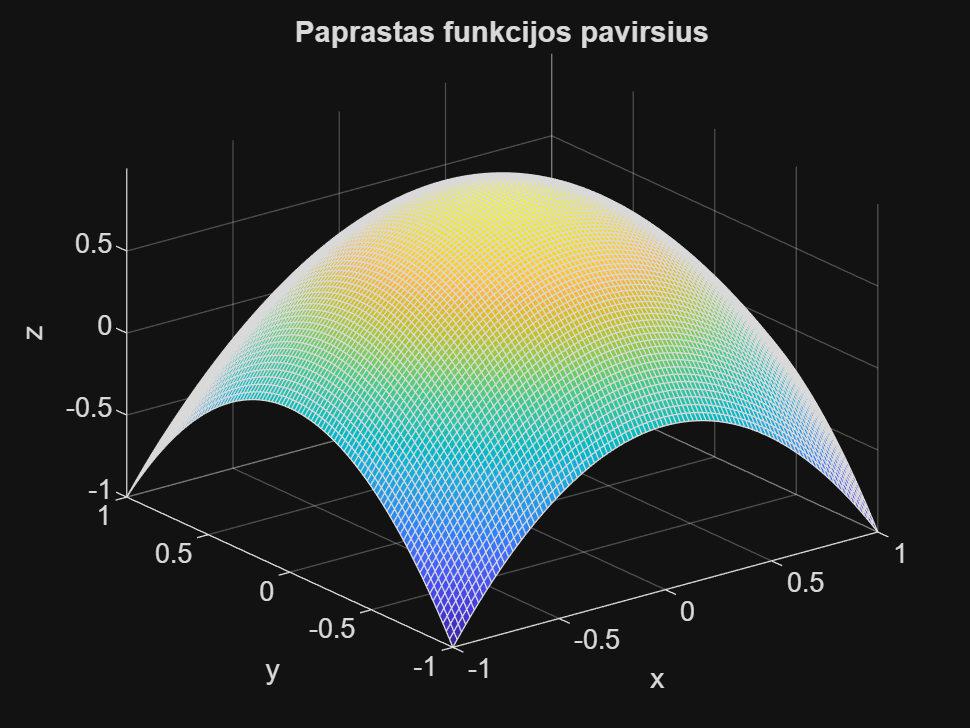



%C
figure;

surf(X,Y,Z);

xlabel('x');
ylabel('y');
zlabel('z');
title('Paprastas funkcijos pavirsius');

grid on;
axis tight;
view(3);
colormap(parula);(parula);